clc;
clear;
l1=30; %Length of Link 1
l2=30; %Length of Link 2
l3=10;  %Length of Link 3
l4 =10; %Length of Link 4

%   DH  = [  a_n  alpha_n  d_n  theta_n]
DHparameter=[0 0 0.04 0;
             0.12 pi/2 0 13*pi/30;
             0.194 0 0 -23*pi/30;
             0 -pi/2 0.176 0;
             0 pi/2 0 pi/2;
             0 pi/2 0 0]

DHparameter =          0         0    0.0400         0
    0.1200    1.5708         0    1.3614
    0.1940         0         0   -2.4086
         0   -1.5708    0.1760         0
         0    1.5708         0    1.5708
         0    1.5708         0         0


## `Defining the asymmetric robot as a rigid tree`

%Defining a Robot Rigid Body Tree 
dental = rigidBodyTree("MaxNumBodies",6,"DataFormat","column");

%Setting the Gravity matrix w.r.t to the base frame of robot.
dental.Gravity = [0 0 -9.81];

%Creating links and joints
body1 = rigidBody('Body1');
joint1 = rigidBodyJoint('Joint1','revolute');
body1.Mass = 10;
body1.CenterOfMass = [0 0 0];
body2 = rigidBody('Body2');
joint2 = rigidBodyJoint('Joint2','revolute');
body2.Mass = 10;
body2.CenterOfMass = [0 0 0];
body3 = rigidBody('Body3');
joint3 = rigidBodyJoint('Joint3','revolute');
body3.Mass = 10;
joint3.PositionLimits = [-10 10]; %Position limit defines the maximum extension/retraction from mean position for a prismatic joint. 
body3.CenterOfMass = [0 0 0];
body4 = rigidBody('Body4');
joint4 = rigidBodyJoint('Joint4','revolute');
body4.Mass = 10;

body5 = rigidBody('Body5');
joint5 = rigidBodyJoint('Joint5','revolute');
body5.Mass = 10;

body6 = rigidBody('Body6');
joint6 = rigidBodyJoint('Joint6','revolute');
body6.Mass = 10;

%Settings the transformations to each joint with DH parameter.
%Assigning the joint of each link with the object 
setFixedTransform(joint1,DHparameter(1,:),"dh");
body1.Joint = joint1;
setFixedTransform(joint2,DHparameter(2,:),"dh");
body2.Joint = joint2;
setFixedTransform(joint3,DHparameter(3,:),"dh");
body3.Joint = joint3;
setFixedTransform(joint4,DHparameter(4,:),"dh");
body4.Joint = joint4;
setFixedTransform(joint5,DHparameter(5,:),"dh");
body5.Joint = joint5;
setFixedTransform(joint6,DHparameter(6,:),"dh");
body6.Joint = joint6;

addBody(dental,body1,'base');
addBody(dental,body2,'Body1');
addBody(dental,body3,'Body2');
addBody(dental,body4,'Body3');
addBody(dental,body5,'Body4');
addBody(dental,body6,'Body5');

showdetails(dental)

--------------------
Robot: (6 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1      revolute             base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  
   6        Body6        Joint6      revolute            Body5(5)   
--------------------


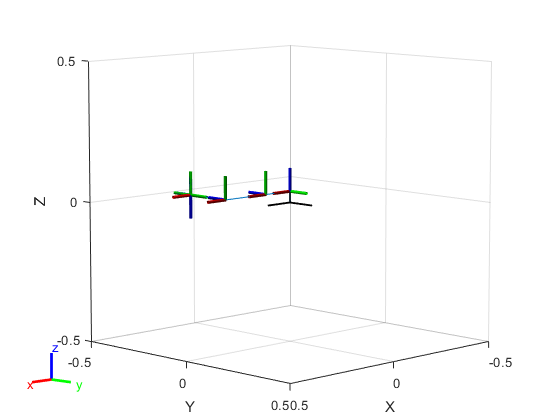


show(dental);

## `Denture, 3 - Teeth, 1 - Tooth, Final Tooth, Transformation and Shrink`

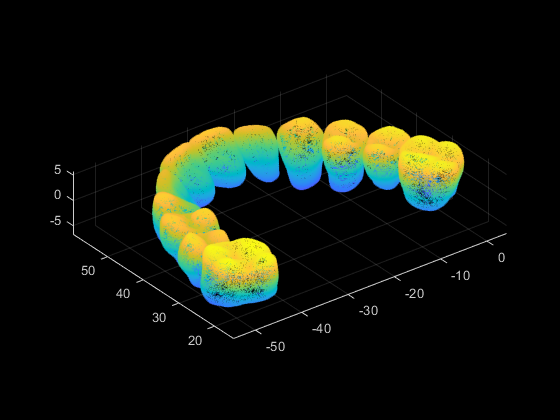

% Read and plot complete denture
stlData = stlread('1-3dm.stl');
points = stlData.Points;
ptCloud = pointCloud(points);
figure
pcshow(ptCloud)

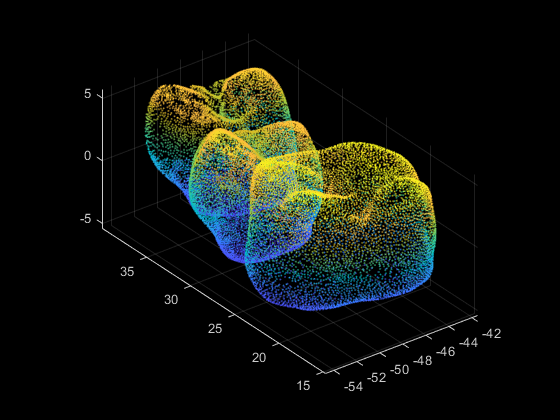


% Select and plot three teeth individually
roi = [-60 -40 10 40 -6 6]; % region of interest
indices = findPointsInROI(ptCloud,roi);
ptCloudB = select(ptCloud, indices);
pcshow(ptCloudB.Location);

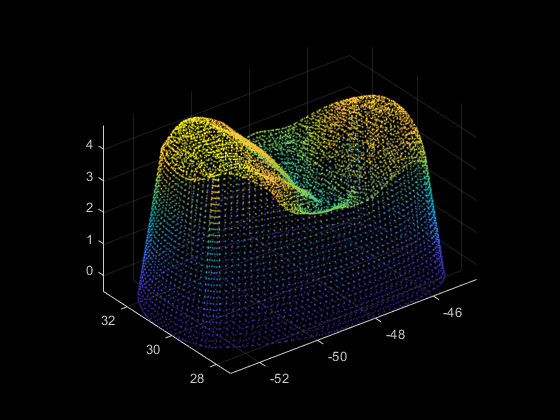


% Import and plot final model individually
stlData_fin = stlread("1tooth_mesh2.STL");

points_fin= stlData_fin.Points;
ptCloud_fin = pointCloud(points_fin);
pcshow(ptCloud_fin);

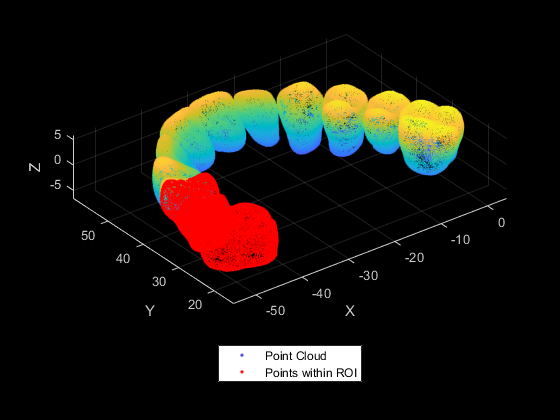


% Three teeth in the denture
figure
pcshow(ptCloud);
hold on;
pcshow(ptCloudB.Location,'r');
legend('Point Cloud','Points within ROI','Location','southoutside','Color',[1 1 1])
xlabel('X'); ylabel('Y'); zlabel('Z');
hold off;

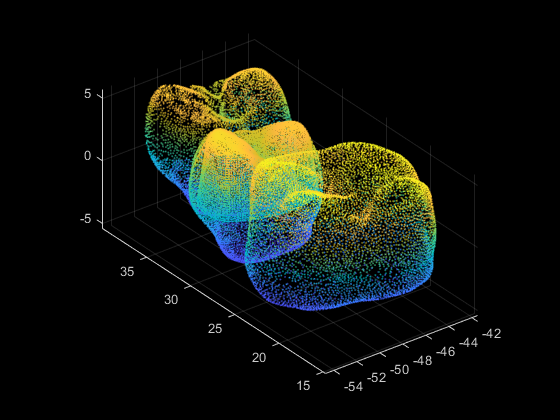


% Final tooth inside the considered tooth
figure
pcshow(ptCloudB.Location);
hold on;
pcshow(ptCloud_fin);
hold off;

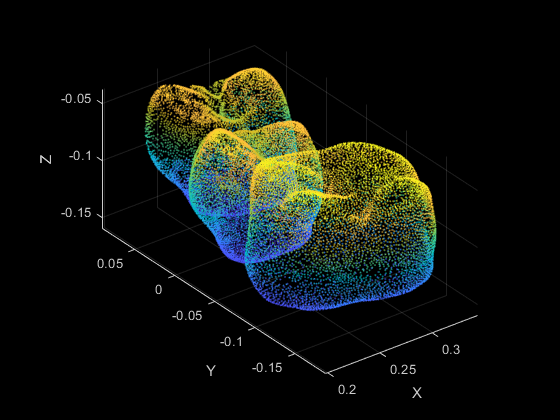


%Transformation (shrink and move)
Sx = 0.011;
Sy = 0.011;
Sz = 0.011;


tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
ptCloud_3t = pctransform(ptCloudB,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);
rot = [1 0 0; 0 1 0; 0 0 1];
zCoord = -0.1;
trans = [0.8 -0.35 zCoord];
tform = rigid3d(rot,trans);
ptCloud_3t = pctransform(ptCloud_3t,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);

figure
pcshow(ptCloud_3t)
xlabel('X'); ylabel('Y'); zlabel('Z')

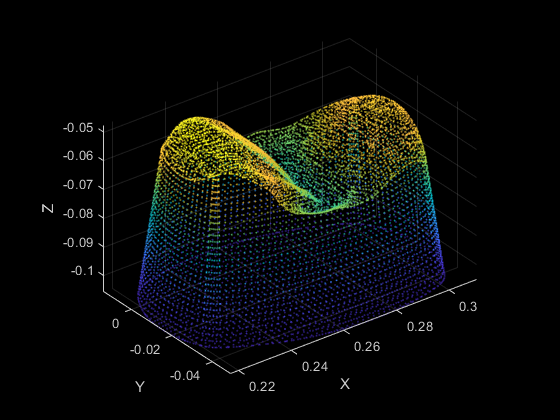

pcshow(ptCloud_fin)
xlabel('X'); ylabel('Y'); zlabel('Z')

## `Curves for end-effector path planning`

Algo

- set Z range

- get Z -> getContour

- get ordered points -> getOrderedPoints()

- smoothen curve -> smoothCurve()

- Make polyshape

- Expand polyshape

figure
allPoints = {};
r = 0.005

r = 0.0050

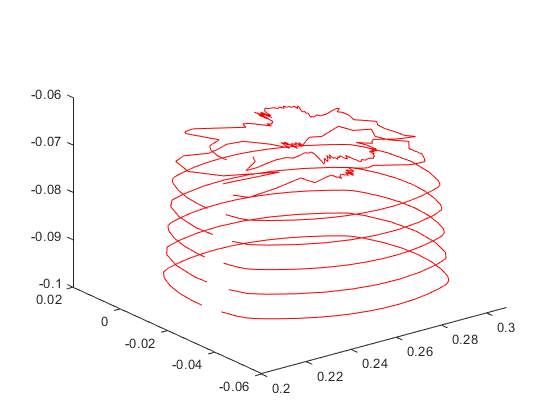

for i=1:7
    L = zCoord + (i-1)*r;
    H = zCoord + r + (i-1)*r;
    [a,b] = getContour(ptCloud_fin,L,H);
    P = getOrderedPoints(a,b);
    [smoothX,smoothY] = smoothCurve(P,35,2);
    
    points = downsample([smoothX',smoothY'],10);
   
    polyin = polyshape({points(:,1)},{points(:,2)});
    polyout = polybuffer(polyin,0.005);
    
    zin = (L+H)/2 * ones(length(polyin.Vertices),1);
    allPoints{i} = [points,zin];
%     zout = (L+H)/2 * ones(length(polyout.Vertices));
    
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),zin,"Color",[1 0 0]); hold on;
%     plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),zout,"Color",[0 1 0]);
end

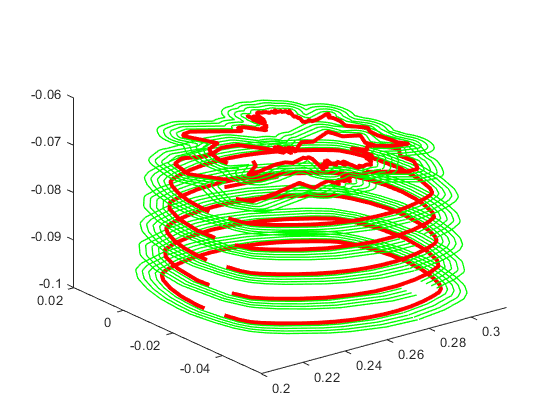

figure
for i=1:length(allPoints)
    polyin = polyshape({allPoints{1,i}(:,1)},{allPoints{1,i}(:,2)});
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),allPoints{1,i}(:,3),...
            "Color",[1 0 0],"LineWidth",3);
    hold on;
    for j=1:4
        polyout = polybuffer(polyin,0.002*j);
        polyout.Vertices = downsample(polyout.Vertices,5);
        z = allPoints{1,i}(1,3)*ones(length(polyout.Vertices),1);
        allPoints{j+1,i} = [polyout.Vertices, z];
        plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),z,...
                "Color",[0 1 0],"LineWidth",1);
    end
end

allPoints

allPoints = 5×7 cell array
    {43×3 double}    {29×3 double}    {43×3 double}    {31×3 double}    {41×3 double}    { 81×3 double}    {164×3 double}
    {45×3 double}    {42×3 double}    {45×3 double}    {42×3 double}    {45×3 double}    {189×3 double}    {313×3 double}
    {45×3 double}    {42×3 double}    {45×3 double}    {42×3 double}    {45×3 double}    {143×3 double}    {228×3 double}
    {45×3 double}    {42×3 double}    {45×3 double}    {42×3 double}    {45×3 double}    {126×3 double}    {183×3 double}
    {45×3 double}    {42×3 double}    {45×3 double}    {42×3 double}    {45×3 double}    {115×3 double}    {153×3 double}


% Row = Top to Bottom - Inside to Outside
% Column = Left to Right - Bottom to Top

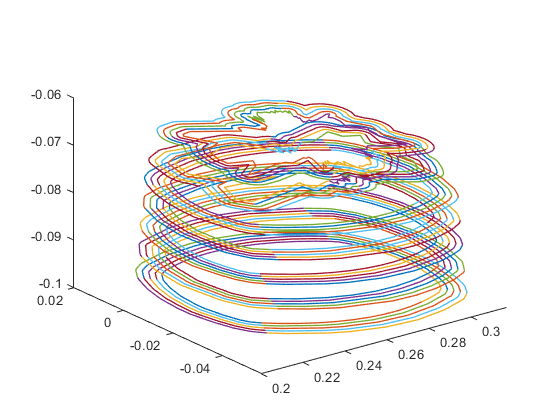

curve1 = allPoints{5,1};
appendAllPoints = [];
figure
for i=1:7
    for j=1:5
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
end

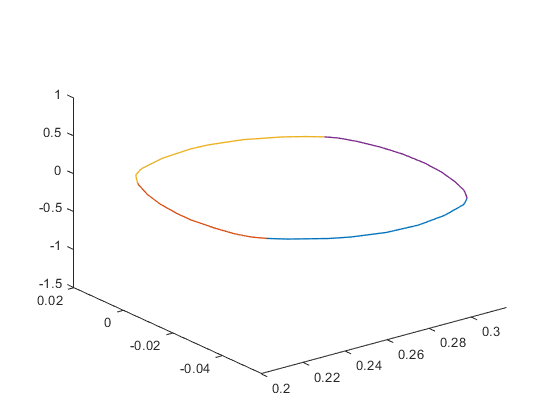

% Show a single curve.
figure
[q1,q2,q3,q4] = getQuarters(allPoints{5,1},1);


% q2 is front
% q1 is right
% q3 is left
% q4 is back



## `Finding the collision free trajectory`

% Need a mesh of the tooth
MSH = collisionMesh(ptCloud_fin.Location)

MSH =   collisionMesh with properties:

    Vertices: [10770×3 double]
        Pose: [4×4 double]


worldCollisionArray = {MSH}

worldCollisionArray = 1×1 cell array
    {1×1 collisionMesh}


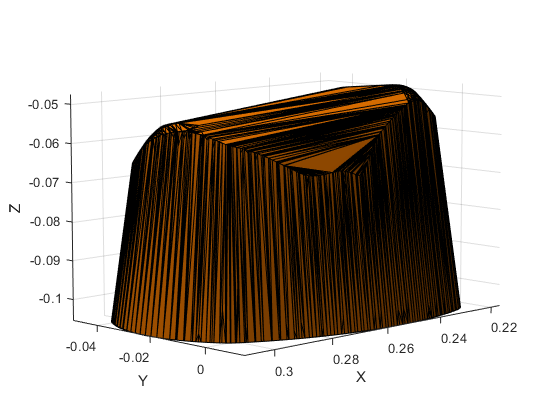

ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);

figure;
% show(dental)
% hold on;
% pcshow(ptCloud_fin)

startPose = trvec2tform([0.220641 -0.0406355 -0.0975])*axang2tform([1 0 0 pi]);
endPose = trvec2tform([0.26 -0.02 0])*axang2tform([1 0 0 pi]);

% Use a fixed random seed to ensure repeatable results
% rng(0);
ik = inverseKinematics("RigidBodyTree",dental);
weights = ones(1,6);
startConfig = ik("Body5",startPose,weights,dental.homeConfiguration);
endConfig = ik("Body5",endPose,weights,dental.homeConfiguration);

% Show initial and final positions
% show(dental,startConfig);
% show(dental,endConfig);

q = trapveltraj([homeConfiguration(dental),startConfig,endConfig],200,"EndTime",2);

% Initialize outputs
inCollision = false(length(q), 1); % Check whether each pose is in collision
worldCollisionPairIdx = cell(length(q),1); % Provide the bodies that are in collision

for i = 1:length(q)
    
    [inCollision(i),sepDist] = checkCollision(dental,q(:,i),worldCollisionArray,"IgnoreSelfCollision","on","Exhaustive","on");
    
    [bodyIdx,worldCollisionObjIdx] = find(isnan(sepDist)); % Find collision pairs
    worldCollidingPairs = [bodyIdx,worldCollisionObjIdx]; 
    worldCollisionPairIdx{i} = worldCollidingPairs;
    
end

%see if there is any collision
isTrajectoryInCollision = any(inCollision)

isTrajectoryInCollision = logical
   0




startPose1 = trvec2tform([0.26 -0.02 0])*axang2tform([1 0 0 pi]);
endPose1 = trvec2tform([0.301326 0.00537663 -0.0775])*axang2tform([1 0 0 pi]);

% Use a fixed random seed to ensure repeatable results
% rng(0);
ik1 = inverseKinematics("RigidBodyTree",dental);
weights = ones(1,6);
startConfig1 = ik1("Body5",startPose,weights,dental.homeConfiguration);
endConfig1 = ik1("Body5",endPose,weights,dental.homeConfiguration);

% Show initial and final positions
% show(dental,startConfig);
% show(dental,endConfig);

q1 = trapveltraj([homeConfiguration(dental),startConfig1,endConfig1],200,"EndTime",2);

% Initialize outputs
inCollision1 = false(length(q1), 1); % Check whether each pose is in collision
worldCollisionPairIdx1 = cell(length(q1),1); % Provide the bodies that are in collision

for i = 1:length(q1)
    
    [inCollision1(i),sepDist1] = checkCollision(dental,q1(:,i),worldCollisionArray,"IgnoreSelfCollision","on","Exhaustive","on");
    
    [bodyIdx1,worldCollisionObjIdx1] = find(isnan(sepDist1)); % Find collision pairs
    worldCollidingPairs1 = [bodyIdx1,worldCollisionObjIdx1]; 
    worldCollisionPairIdx1{i} = worldCollidingPairs1;
    
end

isTrajectoryInCollision1 = any(inCollision1)

isTrajectoryInCollision1 = logical
   0



%inspect detected collisions if any
% if isTrajectoryInCollision
%     
%     collidingIdx1 = find(inCollision,1);
%     collidingIdx2 = find(inCollision,1,"last");
%     
%     % Identify the colliding rigid bodies.
%     collidingBodies1 = worldCollisionPairIdx{collidingIdx1}*[1 0]';
%     collidingBodies2 = worldCollisionPairIdx{collidingIdx2}*[1 0]';
%     
%     % Visualize the environment.
%     ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);
%     
%     % Add the robotconfigurations & highlight the colliding bodies.
%     show(dental,q(:,collidingIdx1),"Parent",ax,"PreservePlot",false);
%     exampleHelperHighlightCollisionBodies(dental,collidingBodies1 + 1,ax);
%     show(dental,q(:,collidingIdx2),"Parent"',ax);
%     exampleHelperHighlightCollisionBodies(dental,collidingBodies2 + 1,ax);
% end

% % Generate Collision Free Trajectory
% intermediatePose1 = trvec2tform([-.3 -.2 .6])*axang2tform([0 1 0 -pi/4]); % Out and around the sphere
% intermediatePose2 = trvec2tform([0.2,0.2,0.6])*axang2tform([1 0 0 pi]); % Come in from above
% 
% intermediateConfig1 = ik("EndEffector_Link",intermediatePose1,weights,q(:,collidingIdx1));
% intermediateConfig2 = ik("EndEffector_Link",intermediatePose2,weights,q(:,collidingIdx2));
% 
% % Show the new intermediate poses
% ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);
% show(robot,intermediateConfig1,"Parent",ax,"PreservePlot",false);
% show(robot,intermediateConfig2,"Parent",ax);

## `Helper Functions`

### `getContour`

function [a,b] = getContour(ptCloud,L,H)
    k = 1;
    
    for i = 1:length(ptCloud.Location(:,3))
        j = ptCloud.Location(i,3);
        if j < H && j > L
            a(k,1) = ptCloud.Location(i,1);
            b(k,1) = ptCloud.Location(i,2);
            k = k+1;
        end
    end
end

### `getOrderedPoints`

function [P] = getOrderedPoints(a,b)
    P = [a'; b']; % coordinates / points 
    c = mean(P,2); % mean/ central point 
    d = P-c ; % vectors connecting the central point and the given points 
    th = atan2(d(2,:),d(1,:)); % angle above x axis
    [th, idx] = sort(th);   % sorting the angles 
    P = P(:,idx); % sorting the given points
    P = [P P(:,1)]; % add the first at the end to close the polygon 
end

### `smoothCurve`

function [smoothX, smoothY] = smoothCurve(P,windowWidth,polynomialOrder)
    smoothX = sgolayfilt(P(1,:), polynomialOrder, windowWidth);
    smoothY = sgolayfilt(P(2,:), polynomialOrder, windowWidth);
end

### `getQuarters`

function [q1,q2,q3,q4] = getQuarters(curve1,flag)    
    a = floor(length(curve1)/4);
    curve1 = circshift(curve1,floor(a/2));
    curve1 = [curve1; curve1(1,:)];
    q1 = [curve1((1:a),1),curve1((1:a),2),curve1((1:a),3)];
    q2 = [curve1((a:2*a),1),curve1((a:2*a),2),curve1((a:2*a),3)];
    q3 = [curve1((2*a:3*a),1),curve1((2*a:3*a),2),curve1((2*a:3*a),3)];
    q4 = [curve1((3*a:end),1),curve1((3*a:end),2),curve1((3*a:end),3)];
    
    if(flag==1)
        plot3(q1(:,1),q1(:,2),q1(:,3),"LineWidth",1);hold on;
        plot3(q2(:,1),q2(:,2),q2(:,3),"LineWidth",1);hold on;
        plot3(q3(:,1),q3(:,2),q3(:,3),"LineWidth",1);hold on;
        plot3(q4(:,1),q4(:,2),q4(:,3),"LineWidth",1);hold on;
    end
end

function [ax, figHandle] = exampleHelperVisualizeCollisionEnvironment(collisionObjectArray)
%exampleHelperVisualizeCollisionEnvironment Visualize a set of collision objects
%   given a cell array of collision objects, create a figure that plots
%   these and with hold on. Return the handle to the figure's axis.
figHandle = figure;

% Show the first object
show(collisionObjectArray{1});

% Get axis properties and set hold
ax = gca;
hold all;

% Show remaining objects
for i = 2:numel(collisionObjectArray)
    show(collisionObjectArray{i}, "Parent", ax);
end

% Set axis properties
axis equal;

end